# Ejercicio Nº2

clear;clc;

Se definen simbólicas las variables

syms t vc(t) il(t) C L R1 R2 E;

Se plantean las ecuaciones y se obtienen las matrices de la forma generalizada

M=[-C 0;0 L]

$$M = \left(\begin{array}{cc} -C & 0\\ 0 & L \end{array}\right)$$

N=[-1/R1 -1;-1 R2]

$$N = \left(\begin{array}{cc} -\frac{1}{R_{1}} & -1\\ -1 & R_{2} \end{array}\right)$$

u=[-E/R1;0]

$$u = \left(\begin{array}{c} -\frac{\text{E}}{R_{1}}\\ 0 \end{array}\right)$$

Se expresan las matrices de la forma normalizada

A=-1.*(M\N)

$$A = \left(\begin{array}{cc} -\frac{1}{C\,R_{1}} & -\frac{1}{C}\\ \frac{1}{L} & -\frac{R_{2}}{L} \end{array}\right)$$


B=M\u

$$B = \left(\begin{array}{c} \frac{\text{E}}{C\,R_{1}}\\ 0 \end{array}\right)$$

Se definen las variables de estado

x=[vc;il]

$$x(t) = \left(\begin{array}{c} \mathrm{vc}\left(t\right)\\ \mathrm{il}\left(t\right) \end{array}\right)$$

Expresando el sistema en forma diferencial

odes = diff(x) ==  A*x + B

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\mathrm{vc}\left(t\right)=\frac{\text{E}}{C\,R_{1}}-\frac{\mathrm{vc}\left(t\right)}{C\,R_{1}}-\frac{\mathrm{il}\left(t\right)}{C}\\ \frac{\partial }{\partial t}\mathrm{il}\left(t\right)=\frac{\mathrm{vc}\left(t\right)}{L}-\frac{R_{2}\,\mathrm{il}\left(t\right)}{L} \end{array}\right)$$

Resolviendo el sistema con el comando dsolve

[vSol(t), iSol(t)] = dsolve(odes);

**Tensión del capacitor**

vSol(t) = simplify(vSol(t))

$$vSol(t) = \begin{array}{l} \frac{{\mathrm{e}}^{-\sigma_{1}}\,\left(\text{E}\,{\mathrm{e}}^{\sigma_{1}}+C_{23}\,R_{1}+C_{23}\,R_{2}+C_{24}\,R_{1}\,\sigma_{2}+C_{24}\,R_{2}\,\sigma_{2}\right)}{R_{1}+R_{2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{t\,\left(L+\sqrt{C^{2}\,{R_{1}}^{2}\,{R_{2}}^{2}-4\,C\,L\,{R_{1}}^{2}-2\,C\,L\,R_{1}\,R_{2}+L^{2}}+C\,R_{1}\,R_{2}\right)}{2\,C\,L\,R_{1}}\\ \sigma_{2}={\mathrm{e}}^{\frac{t\,\sqrt{C^{2}\,{R_{1}}^{2}\,{R_{2}}^{2}-4\,C\,L\,{R_{1}}^{2}-2\,C\,L\,R_{1}\,R_{2}+L^{2}}}{C\,L\,R_{1}}} \end{array}$$

**Corriente del inductor**

iSol(t) = simplify(iSol(t))

$$iSol(t) = \begin{array}{l} {\mathrm{e}}^{-\frac{t\,\sigma_{4}}{2\,C\,L\,R_{1}}}\,\left(R_{2}-\frac{\sigma_{4}}{2\,C\,R_{1}}\right)\,\left(C_{23}-\frac{2\,C\,\text{E}\,L\,R_{1}\,\sigma_{1}\,{\mathrm{e}}^{\sigma_{5}}\,\sigma_{2}}{\sigma_{4}\,\sigma_{6}}\right)+{\mathrm{e}}^{-\frac{t\,\sigma_{3}}{2\,C\,L\,R_{1}}}\,\left(R_{2}-\frac{\sigma_{3}}{2\,C\,R_{1}}\right)\,\left(C_{24}+\frac{2\,C\,\text{E}\,L\,R_{1}\,\sigma_{1}\,{\mathrm{e}}^{-\sigma_{5}}\,\sigma_{2}}{\sigma_{3}\,\sigma_{6}}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{\frac{R_{2}\,t}{2\,L}}\\ \sigma_{2}={\mathrm{e}}^{\frac{t}{2\,C\,R_{1}}}\\ \sigma_{3}=L-\sigma_{6}+C\,R_{1}\,R_{2}\\ \sigma_{4}=L+\sigma_{6}+C\,R_{1}\,R_{2}\\ \sigma_{5}=\frac{t\,\sigma_{6}}{2\,C\,L\,R_{1}}\\ \sigma_{6}=\sqrt{C^{2}\,{R_{1}}^{2}\,{R_{2}}^{2}-4\,C\,L\,{R_{1}}^{2}-2\,C\,L\,R_{1}\,R_{2}+L^{2}} \end{array}$$

Reemplazando los valores de E,R1, R2, L y C

clear C L R1 R2 E;
syms C1 C2;
R1=1;R2=1;L=1;C=1;E=1;
A=subs(A);
B=subs(B);

## Autovalores del circuito 

autovalores= eig(A)

$$autovalores = \left(\begin{array}{c} -1-\mathrm{i}\\ -1+\mathrm{i} \end{array}\right)$$

Las ecuaciones diferenciales son

odes = diff(x) == A*x + B

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\mathrm{vc}\left(t\right)=1-\mathrm{vc}\left(t\right)-\mathrm{il}\left(t\right)\\ \frac{\partial }{\partial t}\mathrm{il}\left(t\right)=\mathrm{vc}\left(t\right)-\mathrm{il}\left(t\right) \end{array}\right)$$

## Estableciendo condiciones iniciales y tiempo de simulación

Para el primer par de condiciones iniciales

v0=1;
i0=1;
ti=0;
tf=4*pi;
Xant=[v0;i0];
constantes=x(0)==Xant;
[vSol(t), iSol(t)] = dsolve(odes,constantes)

$$vSol(t) = \frac{{\mathrm{e}}^{-t}\,\cos\left(t\right)}{2}+\frac{{\mathrm{e}}^{-t}\,\sin\left(t\right)}{2}+\frac{1}{2}$$

$$iSol(t) = \frac{{\mathrm{e}}^{-t}\,\cos\left(t\right)}{2}-\frac{{\mathrm{e}}^{-t}\,\sin\left(t\right)}{2}+\frac{1}{2}$$

Para el segundo par de condiciones iniciales

clear t;
syms t;
v0=-1;
i0=-1;
ti=0;
tf=4*pi;
Xant=[v0;i0];
constantes=x(0)==Xant;
[v2Sol(t), i2Sol(t)] = dsolve(odes,constantes)

$$v2Sol(t) = \frac{1}{2}-\frac{3\,{\mathrm{e}}^{-t}\,\sin\left(t\right)}{2}-\frac{3\,{\mathrm{e}}^{-t}\,\cos\left(t\right)}{2}$$

$$i2Sol(t) = \frac{3\,{\mathrm{e}}^{-t}\,\sin\left(t\right)}{2}-\frac{3\,{\mathrm{e}}^{-t}\,\cos\left(t\right)}{2}+\frac{1}{2}$$

Gráfico de las soluciones

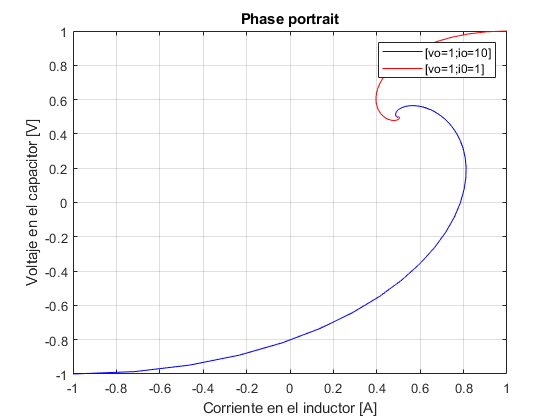

h=0.1;
t=ti:h:tf;
b=plot(i2Sol(t),v2Sol(t),'-b',iSol(t),vSol(t),'-r');
title('Phase portrait')
xlabel('Corriente en el inductor [A]')
ylabel('Voltaje en el capacitor [V]')
grid on
legend({'[vo=1;io=10]','[vo=1;i0=1]'})
xlim([-1.00 1.00])
ylim([-1.00 1.00])